## `Globals1D`

clear all
% Purpose: declare global variables
global N Nfp Np K
global r x  VX
global Dr LIFT
global nx Fx Fscale
global vmapM vmapP vmapB mapB Fmask
global vmapI vmapO mapI mapO
global rx J
global rk4a rk4b rk4c
global Nfaces EToE EToF
global V invV
global NODETOL

% Low storage Runge-Kutta coefficients
rk4a = [            0.0 ...
    -567301805773.0/1357537059087.0 ...
    -2404267990393.0/2016746695238.0 ...
    -3550918686646.0/2091501179385.0  ...
    -1275806237668.0/842570457699.0];
rk4b = [ 1432997174477.0/9575080441755.0 ...
    5161836677717.0/13612068292357.0 ...
    1720146321549.0/2090206949498.0  ...
    3134564353537.0/4481467310338.0  ...
    2277821191437.0/14882151754819.0];
rk4c = [             0.0  ...
    1432997174477.0/9575080441755.0 ...
    2526269341429.0/6820363962896.0 ...
    2006345519317.0/3224310063776.0 ...
    2802321613138.0/2924317926251.0];
rk4a

rk4a =          0   -0.4179   -1.1922   -1.6978   -1.5142


`% Order of polymomials used for approximation`

N = 2

N = 2

`Generate simple equidistant grid with K elements`

K = 20;
xmax = 1;
xmin = 0.;

Nv = K+1;
% Generate node coordinates
VX = (1:Nv);
for i = 1:Nv
    VX(i) = (xmax-xmin)*(i-1)/(Nv-1) + xmin;
end
% read element to node connectivity
EToV = zeros(K, 2);
for k = 1:K
    EToV(k,1) = k; EToV(k,2) = k+1;
end

EToV

EToV =      1     2
     2     3
     3     4
     4     5
     5     6
     6     7
     7     8
     8     9
     9    10
    10    11


## `% Initialize solver and construct grid and metric; `

## `StartUp1D;`

`% Definition of constants`

Globals1D; NODETOL = 1e-10;
Np = N+1; Nfp = 1; Nfaces=2;

`% Compute basic Legendre Gauss Lobatto grid`

`r ``=` `JacobiGL``(``0``,``0``,N);`

% function [x] = JacobiGL(alpha,beta,N)
% Purpose: Compute the N'th order Gauss Lobatto quadrature
%          points, x, associated with the Jacobi polynomial,
%          of type (alpha,beta) > -1 ( <> -0.5).
alpha = 0; beta = 0;

x = zeros(N+1,1);
if (N==1) x(1)=-1.0; x(2)=1.0; return; end;

[xint,w] = JacobiGQ(alpha+1,beta+1,N-2);
x = [-1, xint', 1]';
x

x =     -1
     0
     1


w

w = 2

r = x

r =     -1
     0
     1


`Vandermonde1D``(``N``,``r``)`

V = zeros(length(r),N+1);
for j=1:N+1
    V(:,j) = JacobiP(r(:), 0, 0, j-1);
end;
V

V =     0.7071   -1.2247    1.5811
    0.7071         0   -0.7906
    0.7071    1.2247    1.5811


invV = inv(V);


`Dmatrix1D`

Vr = GradVandermonde1D(N, r);
Dr = Vr/V

Dr =    -1.5000    2.0000   -0.5000
   -0.5000         0    0.5000
    0.5000   -2.0000    1.5000


`% Create surface integral terms LIFT ``=` `Lift1D``();`

Emat = zeros(Np,Nfaces*Nfp);

% Define Emat
Emat(1,1) = 1.0; Emat(Np,2) = 1.0;

% inv(mass matrix)*\s_n (L_i,L_j)_{edge_n}
LIFT = V*(V'*Emat)

LIFT =     4.5000    1.5000
   -0.7500   -0.7500
    1.5000    4.5000


`% build coordinates of all the nodes`

va = EToV(:,1)'; vb = EToV(:,2)';
x = ones(N+1,1)*VX(va) + 0.5*(r+1)*(VX(vb)-VX(va));
x

x =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500
    0.0250    0.0750    0.1250    0.1750    0.2250    0.2750    0.3250    0.3750    0.4250    0.4750    0.5250    0.5750    0.6250    0.6750    0.7250    0.7750    0.8250    0.8750    0.9250    0.9750
    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


`% calculate geometric factors [``rx``,``J``] ``=` `GeometricFactors1D``(``x``,``Dr``)`

xr  = Dr*x; J = xr; rx = 1./J;

`% Compute masks for edge nodes`

fmask1 = find( abs(r+1) < NODETOL)';
fmask2 = find( abs(r-1) < NODETOL)';
Fmask  = [fmask1;fmask2]'

Fmask =      1     3


Fx = x(Fmask(:), :)

Fx =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500
    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


`% Build surface normals and inverse metric at surface`

nx = zeros(Nfp*Nfaces, K);

% Define outward normals
nx(1, :) = -1.0; nx(2, :) = 1.0;

Fscale = 1./(J(Fmask,:));
nx

nx =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


Fscale

Fscale =    40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000
   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000


`% Build connectivity matrix`

[EToE, EToF] = Connect1D(EToV)

EToE =      1     2
     1     3
     2     4
     3     5
     4     6
     5     7
     6     8
     7     9
     8    10
     9    11


EToF =      1     1
     2     1
     2     1
     2     1
     2     1
     2     1
     2     1
     2     1
     2     1
     2     1


`% Build connectivity maps`

[vmapM, vmapP, vmapB, mapB] = BuildMaps1D

vmapM =      1
     3
     4
     6
     7
     9
    10
    12
    13
    15


vmapP =      1
     4
     3
     7
     6
    10
     9
    13
    12
    16


vmapB =      1
    60


mapB =      1
    40


`% Set initial conditions`

u = sin(2*pi*x)

u =          0    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090
    0.1564    0.4540    0.7071    0.8910    0.9877    0.9877    0.8910    0.7071    0.4540    0.1564   -0.1564   -0.4540   -0.7071   -0.8910   -0.9877   -0.9877   -0.8910   -0.7071   -0.4540   -0.1564
    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000


`% Solve Problem`

FinalTime = 2;

`[``u``] ``=` `Advec1D``(``u``, ``FinalTime``)`

time = 0;
% Runge-Kutta residual storage
resu = zeros(Np,K);

% compute time step size
xmin = min(abs(x(1,:)-x(2,:)));
CFL=0.75; dt   = CFL/(2*pi)*xmin; dt = .5*dt;
Nsteps = ceil(FinalTime/dt); dt = FinalTime/Nsteps;

% advection speed
a = (2*pi);

% outer time step loop
for tstep=1:Nsteps
    for INTRK = 1:5
        timelocal = time + rk4c(INTRK)*dt;
        
        % form field differences at faces
        alpha=1;
        du = zeros(Nfp*Nfaces,K);
        du(:) = (u(vmapM)-u(vmapP)).*(a*nx(:)-(1-alpha)*abs(a*nx(:)))/2;
        
        % impose boundary condition at x=0
        uin = -sin(a*a*timelocal);
        du(mapI) = (u(vmapI)- uin ).*(a*nx(mapI)-(1-alpha)*abs(a*nx(mapI)))/2;
        du(mapO) = 0;
        
        % compute right hand sides of the semi-discrete PDE
        rhsu = -a*rx.*(Dr*u) + LIFT*(Fscale.*(du));
        resu = rk4a(INTRK)*resu + dt*rhsu;
        u = u+rk4b(INTRK)*resu;
    end
    % Increment time
    time = time+dt;
end



Testing outputs

mapI

mapI = 1

mapO

mapO = 40

vmapM'

ans =      1     3     4     6     7     9    10    12    13    15    16    18    19    21    22    24    25    27    28    30    31    33    34    36    37    39    40    42    43    45    46    48    49    51    52    54    55    57    58    60


vmapP'

ans =      1     4     3     7     6    10     9    13    12    16    15    19    18    22    21    25    24    28    27    31    30    34    33    37    36    40    39    43    42    46    45    49    48    52    51    55    54    58    57    60


Fscale

Fscale =    40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000
   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000


LIFT

LIFT =     4.5000    1.5000
   -0.7500   -0.7500
    1.5000    4.5000


rx

rx =    40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000
   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000
   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000


Dr

Dr =    -1.5000    2.0000   -0.5000
   -0.5000         0    0.5000
    0.5000   -2.0000    1.5000


du

du =    -0.0001   -0.0032   -0.0001   -0.0028    0.0002   -0.0019    0.0012   -0.0011    0.0023   -0.0004    0.0032   -0.0000    0.0033   -0.0002    0.0027   -0.0010    0.0018   -0.0019    0.0007   -0.0028
   -0.0032   -0.0001   -0.0028    0.0002   -0.0019    0.0012   -0.0011    0.0023   -0.0004    0.0032   -0.0000    0.0033   -0.0002    0.0027   -0.0010    0.0018   -0.0019    0.0007   -0.0028         0


du(3)

ans = -0.0032

rhsu

rhsu =    36.0667   39.2736   38.5979   34.0865   26.3149   15.9096    3.9706   -8.3475  -19.8801  -29.4274  -36.1290  -39.2706  -38.5786  -34.1105  -26.2964  -15.9180   -3.9716    8.3546   19.8714   29.4342
   38.1579   39.4304   36.7809   30.5778   21.3659   10.0506   -2.2199  -14.3063  -24.9639  -33.1967  -38.1712  -39.4102  -36.7949  -30.5731  -21.3626  -10.0585    2.2288   14.2992   24.9677   33.1963
   39.2540   38.5822   34.0915   26.2899   15.8908    3.9585   -8.3814  -19.8834  -29.4535  -36.1293  -39.2764  -38.5742  -34.0977  -26.2845  -15.8951   -3.9552    8.3795   19.8838   29.4547   36.1264


resu

resu =     0.0143    0.0159    0.0159    0.0143    0.0114    0.0073    0.0025   -0.0026   -0.0073   -0.0114   -0.0144   -0.0159   -0.0159   -0.0143   -0.0113   -0.0073   -0.0025    0.0026    0.0073    0.0114
    0.0153    0.0161    0.0153    0.0130    0.0094    0.0049   -0.0000   -0.0050   -0.0095   -0.0130   -0.0153   -0.0161   -0.0153   -0.0130   -0.0094   -0.0049    0.0000    0.0050    0.0095    0.0130
    0.0159    0.0159    0.0143    0.0113    0.0073    0.0025   -0.0026   -0.0074   -0.0114   -0.0144   -0.0159   -0.0159   -0.0143   -0.0113   -0.0073   -0.0025    0.0026    0.0074    0.0114    0.0144


% plot(x, resu)


writematrix(Dr, 'Dr.txt')
writematrix(EToE, 'EToE.txt')
writematrix(EToF, 'EToF.txt')
writematrix(Fmask, 'Fmask.txt')
writematrix(Fscale, 'Fscale.txt')
writematrix(Fx, 'Fx.txt')
writematrix(invV, 'invV.txt')
writematrix(J, 'J.txt')
writematrix(K, 'K.txt')
writematrix(LIFT, 'LIFT.txt')
writematrix(mapB, 'mapB.txt')
writematrix(mapI, 'mapI.txt')
writematrix(mapO, 'mapO.txt')
writematrix(N, 'N.txt')
writematrix(Nfaces, 'Nfaces.txt')
writematrix(Nfp, 'Nfp.txt')
writematrix(NODETOL, 'NODETOL.txt')
writematrix(Np, 'Np.txt')
writematrix(nx, 'nx.txt')
writematrix(r, 'r.txt')
writematrix(rk4a, 'rk4a.txt')
writematrix(rk4b, 'rk4b.txt')
writematrix(rk4c, 'rk4c.txt')
writematrix(rx, 'rx.txt')
writematrix(V, 'V.txt')
writematrix(vmapB, 'vmapB.txt')
writematrix(vmapI, 'vmapI.txt')
writematrix(vmapM, 'vmapM.txt')
writematrix(vmapO, 'vmapO.txt')
writematrix(vmapP, 'vmapP.txt')
writematrix(VX, 'VX.txt')
writematrix(x, 'x.txt')
writematrix(dt, 'dt.txt')
writematrix(invV, 'invV.txt')

% % Create a table with the data and variable names
% T = table(vmapI, 'VariableNames', { 'vmapI'} )
% % Write data to text file
% writetable(T, 'vmapI.txt')
% 
% %
% T = table(vmapO, 'VariableNames', { 'vmapO'} )
% % Write data to text file
% writetable(T, 'vmapO.txt')
% 
% % Create a table with the data and variable names
% T = table(mapI, 'VariableNames', { 'mapI'} )
% % Write data to text file
% writetable(T, 'mapI.txt')
% 
% T = table(mapO, 'VariableNames', { 'mapO'} )
% % Write data to text file
% writetable(T, 'mapO.txt')
% 
% % Create a table with the data and variable names
% T = table(vmapM, 'VariableNames', { 'vmapM'} )
% % Write data to text file
% writetable(T, 'vmapM.txt')
% 
% T = table(vmapP, 'VariableNames', { 'vmapP'} )
% % Write data to text file
% writetable(T, 'vmapP.txt')
% 
% T = table(Fscale, 'VariableNames', { 'Fscale'} )
% % Write data to text file
% writetable(T, 'Fscale.txt')
% 
% T = table(LIFT, 'VariableNames', { 'LIFT'} )
% % Write data to text file
% writetable(T, 'LIFT.txt')
% 
% T = table(rx, 'VariableNames', { 'rx'} )
% % Write data to text file
% writetable(T, 'rx.txt')
% 
% T = table(Dr, 'VariableNames', { 'Dr'} )
% % Write data to text file
% writetable(T, 'Dr.txt')
% 
% T = table(rk4a, 'VariableNames', { 'rk4a'} )
% % Write data to text file
% writetable(T, 'rk4a.txt')
% 
% T = table(rk4b, 'VariableNames', { 'rk4b'} )
% % Write data to text file
% writetable(T, 'rk4b.txt')
% 
% T = table(rk4c, 'VariableNames', { 'rk4c'} )
% % Write data to text file
% writetable(T, 'rk4c.txt')
% 
% T = table(x, 'VariableNames', { 'x'} )
% % Write data to text file
% writetable(T, 'x.txt')
% 
% T = table(N, 'VariableNames', { 'N'} )
% % Write data to text file
% writetable(T, 'N.txt')
% 
% T = table(K, 'VariableNames', { 'K'} )
% % Write data to text file
% writetable(T, 'K.txt')
% 
% T = table(nx, 'VariableNames', { 'nx'} )
% % Write data to text file
% writetable(T, 'nx.txt')


## `Results`

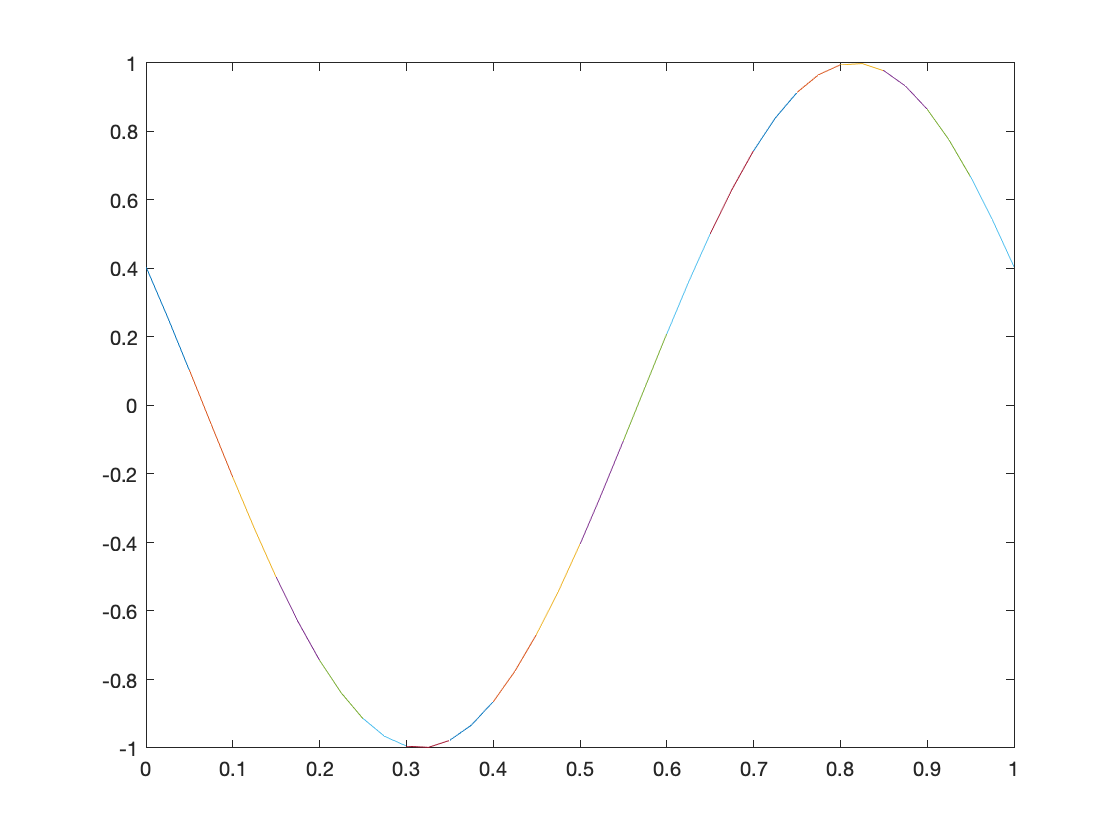

plot(x,u)

`Original code`

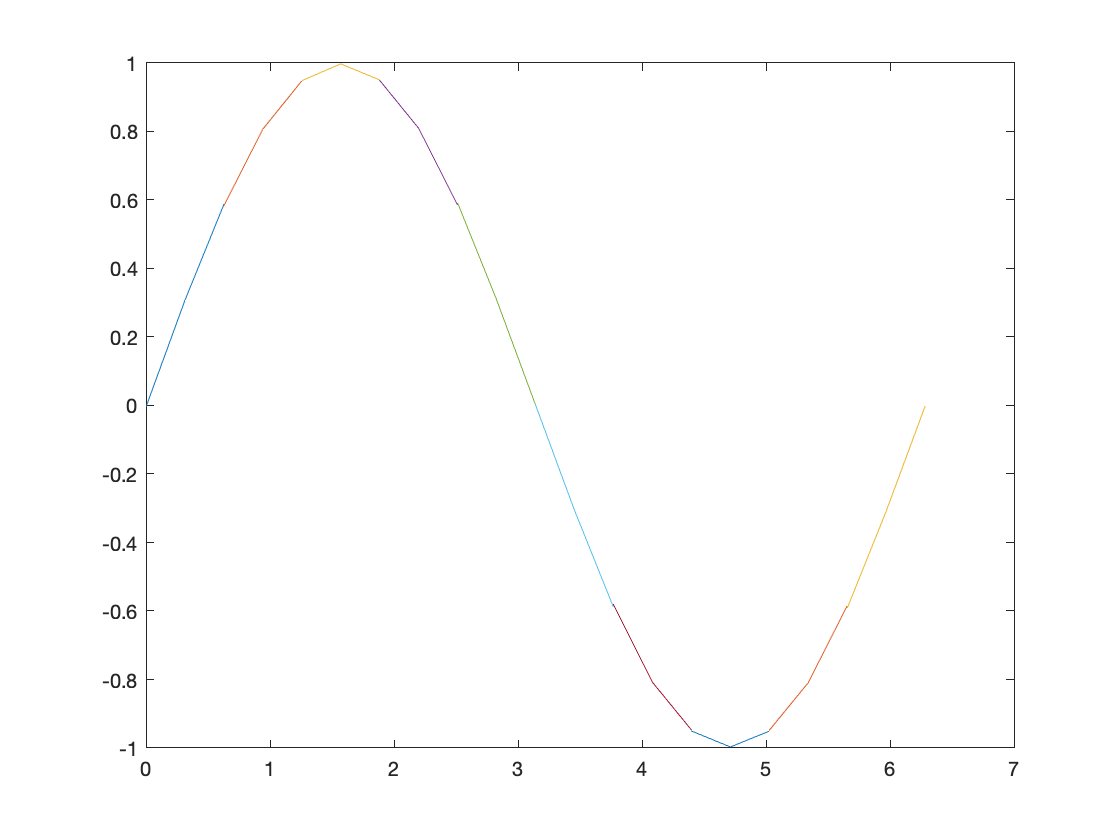

% Driver script for solving the 1D advection equations
Globals1D;

% Order of polymomials used for approximation 
N = 2;

% Generate simple mesh
[Nv, VX, K, EToV] = MeshGen1D(0.0,2. * pi,10);

% Initialize solver and construct grid and metric
StartUp1D;

% Set initial conditions
u = sin(x);

% Solve Problem
FinalTime = 2;
[u] = Advec1D(u,FinalTime);
plot(x,u)